
tic
clc;clear;
close all;
addpath('.\Functions')

## Section 1: Define parameters and Read raw data

FigureParam = InitFigParam();
SignalParam = InitSignalParam();
FilterParam = InitFilterParam(SignalParam);
MicroParam = InitMicroParam(SignalParam,FigureParam);

## Section 2: Generate transmitted signals

chirp = GenerateFMCWSignal(SignalParam);

## Section 3: Design filter to seprate single tone and FMCW signals

Band pass filter (Derive single tone)

[BPF_b,BPF_a] = DesignBPF(FilterParam.F_Center,FilterParam.BPF_Filter_Pass,FilterParam.BPF_Filter_Stop,SignalParam.SampleFrequency,FigureParam);
% High pass filter (Derive FMCW waves)
[HPF_b,HPF_a] = DesignHPF(FilterParam.HPF_Filter_Pass,FilterParam.HPF_Filter_Stop,SignalParam.SampleFrequency,FigureParam);
% Low pass filter (Derive FMCW waves)
[LPF_b,LPF_a] = DesignLPF(FilterParam.LPF_Filter_Pass,FilterParam.LPF_Filter_Stop,SignalParam.SampleFrequency,FigureParam);

## Section 4: Load the voice signal / Generate simulation signal

464894

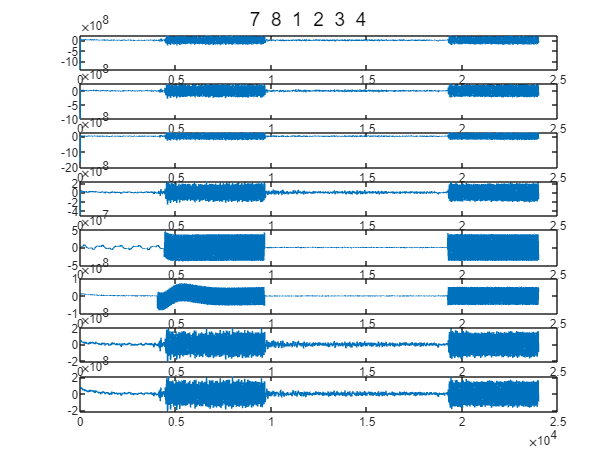

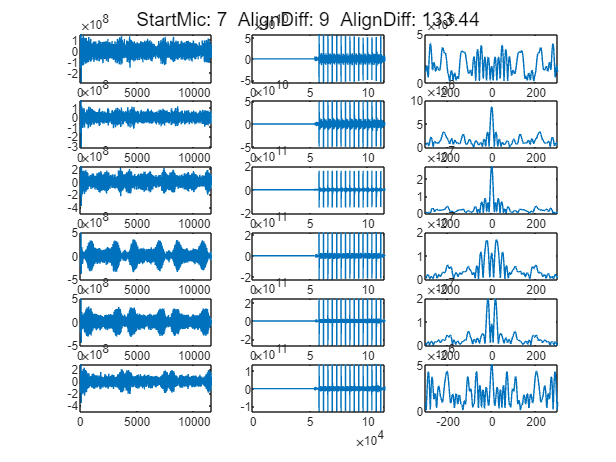

-- raw size old: 359294;
-- raw size old: 8;
-- raw size new: 359221;
-- raw size new: 8;
-- raw size new: 359221;
-- raw size new: 6;
-- Read size: 359221, 6;


[Signal, mic_index] = Load6MicData(SignalParam,FilterParam,'/7');

The peak time is 0.074667, The peak frequency is 18117.187500, The peak energy is 191.242746
tmp8


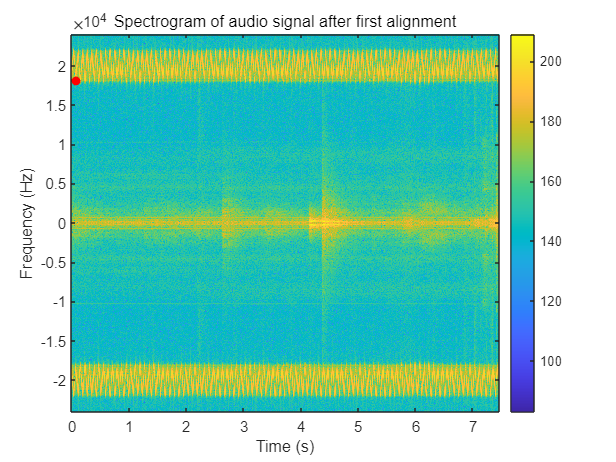



peak_time=0.074667, peak_time_idx=8.000000
-- Read size: 359221, 6;
-- Read size: 355637, 6;


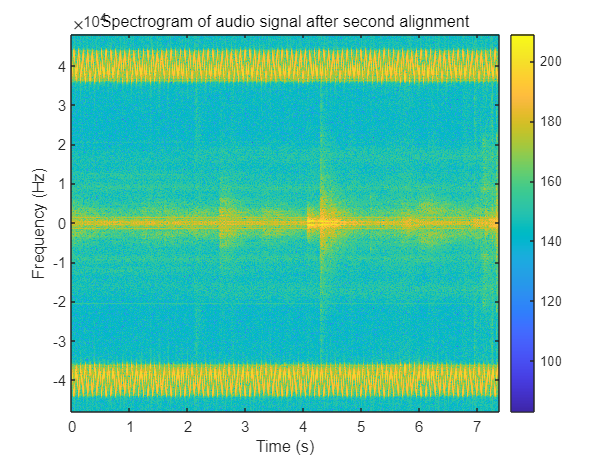

-- Read size: 355637, 6;


[Signal, BGSignal] = align(SignalParam,FilterParam,Signal, mic_index);

读取数据

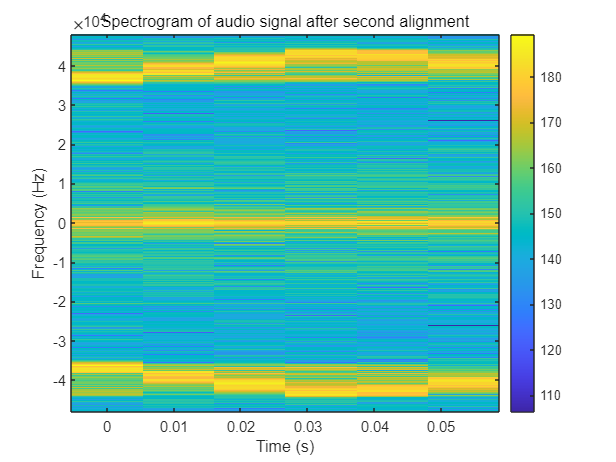

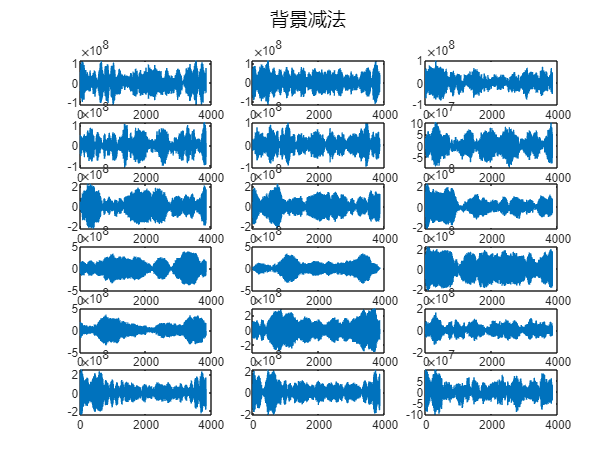

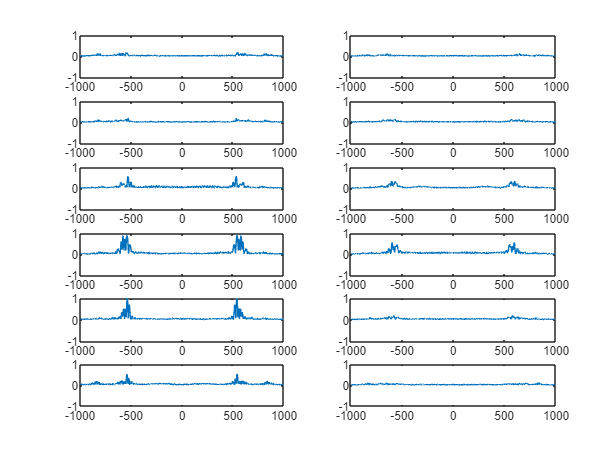

[data,Signal2]=BGSubtraction(SignalParam,FilterParam,Signal,BGSignal,true);

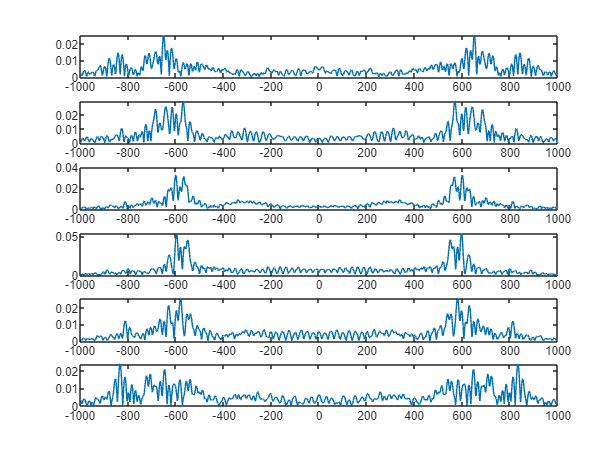

P = Estimation(SignalParam,FilterParam,MicroParam,data,true);

## Section 5: 

trajectory=P;
% figure
% plot(P(1),P(2),'o');
% axis([0.3 0.9 -60 60])
while size(Signal,1)>SignalParam.ChirpSize
    [data,Signal]=BGSubtraction(SignalParam,FilterParam,Signal,BGSignal,false);
    P = Estimation(SignalParam,FilterParam,MicroParam,data,false);
    trajectory=[trajectory;P];
%     hold on;
%     plot(P(1),P(2),'o');
%     axis([0.3 0.9 -60 60]) 

%     pause(SignalParam.ChirpT)
end



figure
subplot(2,1,1)
plot(trajectory(:,1))
ylim([0 2])
                                                                  
subplot(2,1,2)
plot(trajectory(:,2))
ylim([-90 90])


FileName = 'acouRes3.mat';
save(FileName,'trajectory');

% clear;
% load('acouRes1.mat');
% plot(trajectory(:,1));